Electricity Prices (retrieved 9/3/26 @ [Electricity Prices for Netherlands](https://thingler.io/country/Netherlands))

lambda = [12.27 11.2 10.98 11 11.3 11.1 14.09 22.25 24.58 16.49 13.07 10.09 7.62 6.99 7.24 9.13 10.05 12.71 22.34 24.79 21.78 17.06 15.54 13.98];
lambda = kron(lambda, ones(1,Nt/24)); lambda = lambda./Nh; % divide cost into time steps

kb = 1.645e-4; % between floors
kroof = 3.28e-5;
kfacade = 9.67e-5;

A = [-kb-kfacade kb 0 0;
     kb -kb-kb-kfacade kb 0;
     0 kb -kb-kb-kfacade kb;
     0 0 kb -kb-kfacade-kroof];

Bu_k = zeros(4,3,size(lambda,1)); % state selection, input selection, time step in day
B = zeros(4,4,size(lambda,1));

Bd = [kfacade;
      kfacade;
      kfacade;
      kfacade+kroof];

for i = lambda
    Bu_k = [1 0 0;
            0 1 0;
            0 0 1;
            0 0 1] * i;
    B(:,:,i) = [Bu_k, Bd];
end


rank(ctrb(A,B))

C = eye(4); D = zeros(4,4);
tf = ss(A,B,C,D);

%step(tf)
[y,t] = step(tf);

stepinfo(y(:,1 ,1), t) % ~ 10 steps in rise time

Ts = 900; % 15 minute samples
tf_d = c2d(tf, Ts, 'zoh');
A = tf_d.A; B = tf_d.B;

Nt = 60*60*24/Ts; % Number of samples in a day
Nh = 60*60/Ts; % Number of samples in an hour
Nd = Nt/(24*Nh); % Number of days sampled


Problem setup

% Parameters
x0 = [23; 1; 50; 18]; 
x_ref = 20; 
Np = 2*Nt; % 2 days
n = size(B,1); 
m = size(B,2);

% Quadratic cost element (state)
QConst = 1;
Q = QConst * diag([1 1 1 1]); 
Q = kron(eye(Np), Q);
H = [2*Q zeros(Np*n, Np*m);
     zeros(Np*m, Np*n) zeros(Np*m)]; % Cost is only quadratic in state (distance from ref), linear in input

% Linear cost element
% State penalty
F_x = -2*Q*(x_ref*ones(Np*n,1));

% Actuation effort
F_u = kron(ones(1,2),kron(lambda, ones(1,m)))'; % change the 2 here sometime

F = [F_x; F_u];

% State solution phi
% Extended Controllability matrix
Gamma = zeros(Np*n, Np*m);
for i = 1:Np
    for j = 1:i
        Gamma((i-1)*n+1:i*n, (j-1)*m+1:j*m) = A^(i-j)*B; % u_k -> u_k+Np
    end
end
A_phi = [-1*eye(Np*n) Gamma];
% b matrix (A^i X0)
b_phi = zeros(Np*n,1);
for i = 1:Np
    b_phi((i-1)*n+1:i*n) = -A^i*x0;
end

% External Temperature
T_ext = 0;
T_ext_IDs = [0 0 0 1];
A_u_ext = [zeros(Np, Np*n) kron(eye(Np), T_ext_IDs)];
b_u_ext = T_ext * ones(Np,1);

% Change between inputs - |u_k+1 - u_k| <= Delta_u
Delta_u = 1e-4;
A_uDelta = zeros(Np*(m-1), Np*(m+n));
A_template = [1 0 0 0 -1];
for i = 1:m-1
    for j = 1:Np-1
        A_uDelta((j-1)*(m-1)+i, Np*n+(j-1)*(m)+i:Np*n+j*m+i) = A_template;
    end
end
A_uDelta = [A_uDelta; -1*A_uDelta]; % |abc|<= 
b_uDelta = Delta_u * ones(size(A_uDelta,1), 1);

Aineq = [A_uDelta]; Bineq = [b_uDelta];
ub = [100*ones(Np*n,1); 100*ones(Np*m,1)];
lb = [-100*ones(Np*n,1); zeros(Np*m,1)];

Aeq = [A_phi; A_u_ext];
beq = [b_phi; b_u_ext];

[x, fval] = quadprog(H, F, Aineq, Bineq, Aeq, beq, lb, ub);
T1 = x(1:4:Np*n); 
T2 = x(2:4:Np*n); 
T3 = x(3:4:Np*n); 
T4 = x(4:4:Np*n);


Solver stopped prematurely.

quadprog stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



u1 = x(Np*n+1:4:Np*n+Np*m); 
u2 = x(Np*n+2:4:Np*n+Np*m); 
u3 = x(Np*n+3:4:Np*n+Np*m); 
u4 = x(Np*n+4:4:Np*n+Np*m);


Plotting data

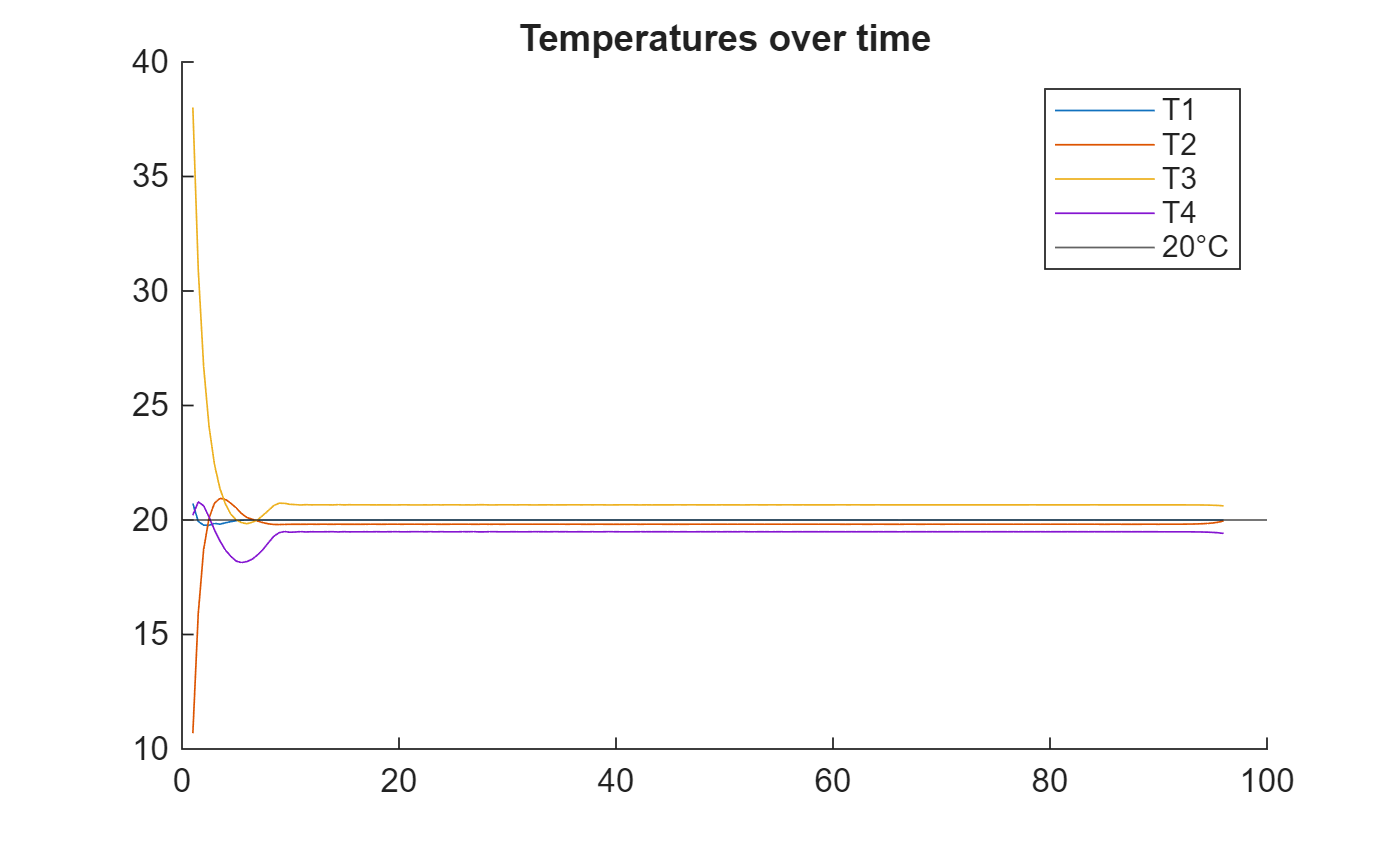

t = linspace(1,Nt, Np); % time in hours
figure;
hold on
plot(t, T1);
plot(t,T2);
plot(t,T3);
plot(t,T4);
yline(x_ref);
title("Temperatures over time")
legend("T1", "T2", "T3", "T4", x_ref+"°C");

figure;
tiledlayout(4,1);
nexttile
stairs(t,u1);

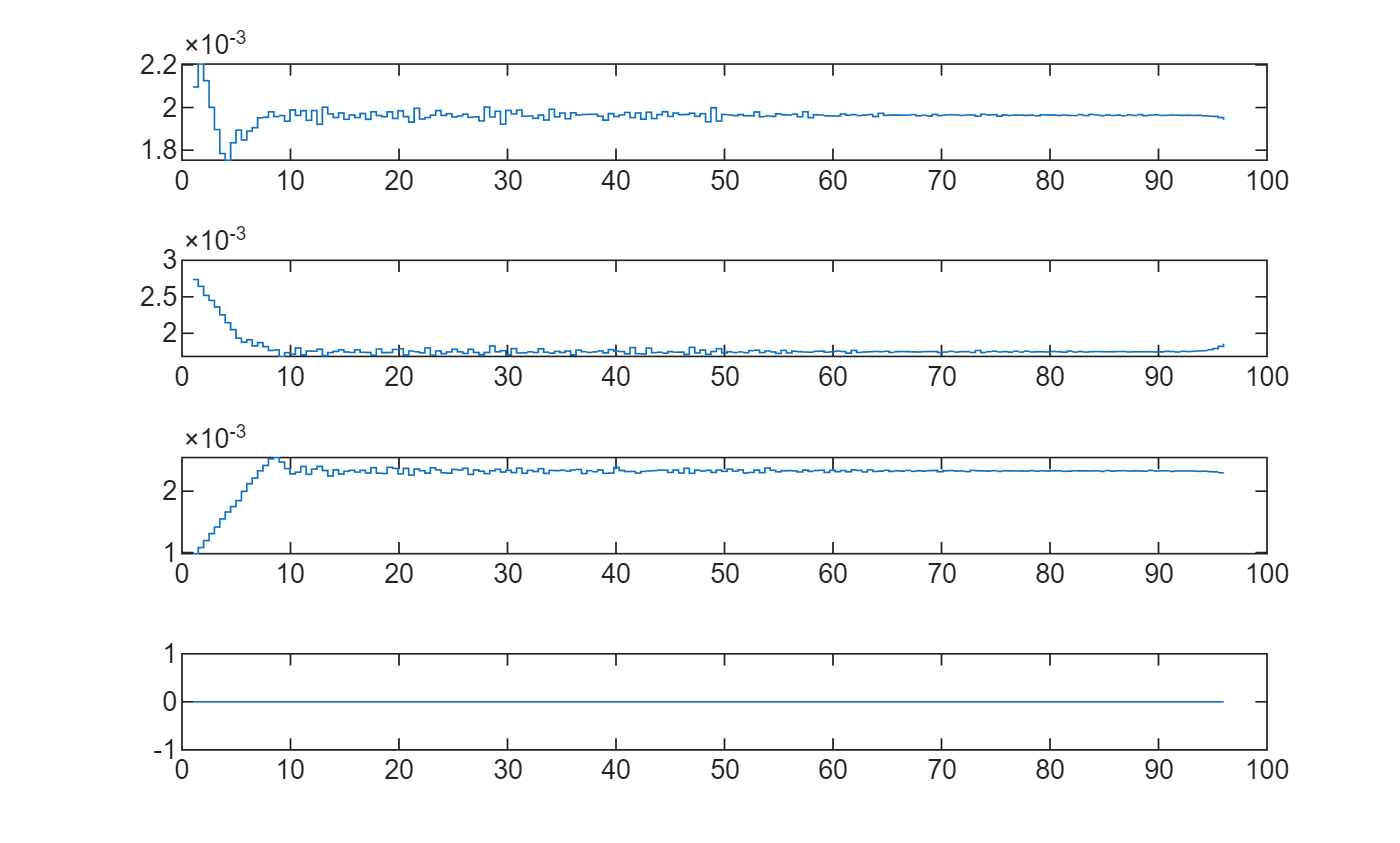

nexttile
stairs(t,u2);
nexttile
stairs(t,u3);
nexttile
stairs(t,u4);